MATLAB In-Class exercises 2

Lecturer: Mokshin V.V.

Student: Galimov M.D.

Group № 4167

Kazan, 2019 

**Exercise 1. **Construct an input space consisting of the polynomials *x^*0,*x^*1, *x^*2,*x^*3, and *x^*4 evaluated over the range [–1,1]. Then generate a weighted sum of these polynomials using random weights (e.g. `randn`). Repeat this a total of 20 times and visualize the results.

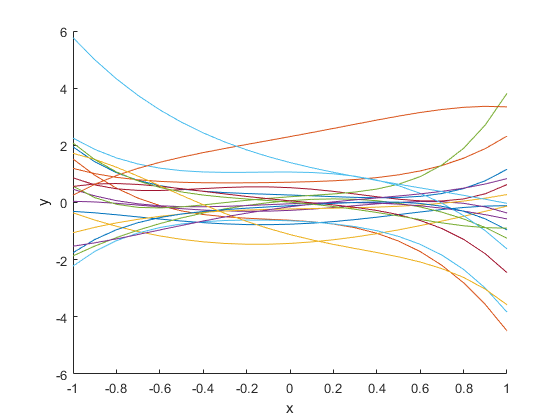

x = -1:0.1:1;
figure;
hold on
for k=1:20
    %generate polunom with random (normal(0, 1)) weights
    y = randn() * x.^4 + randn() * x.^3 +randn() * x.^2 + randn() * x + randn();
    plot(x, y);
end
ylabel('y');
xlabel('x');

**Exercise 2. **Generate some random data using `rand(1,100).^4`. We want to find a value that summarizes the central tendency of these data, and suppose we have chosen the error metric of the sum of the absolute differences between the value and the data points. Plot the error surface, i.e. a function that illustrates the relationship between candidate values and the error associated with these values. For the candidate values, use 100 equally spaced values between 0 and 1 (e.g. `linspace(0,1,100)`.

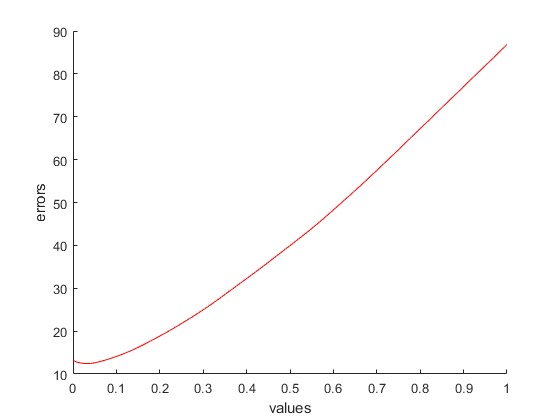

data = rand(1, 100).^4;
candidates = linspace(0, 1, 100);
errors = zeros(1, 100);
for i=1:100
    %fill vector with error metrics
    errors(i)=sum(abs(data-candidates(i)));
end
figure;
hold on;
plot(candidates, errors, 'r');
xlabel('values');
ylabel('errors');

**Exercise 3. **Generate some random data using `x = rand(1,1000); y = x+0.1*randn(1,1000);`. Using ordinary least-squares (OLS), fit a line to these data and visualize the results.

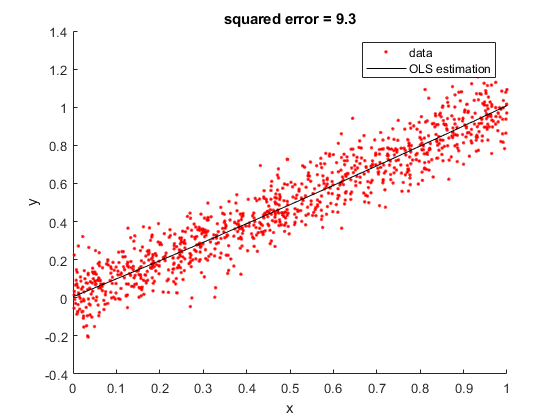

% generate some random data
x = rand(1,1000);
y = x+0.1*randn(1,1000);
% construct the regressor matrix
X = [x(:).^2 x(:) ones(length(x),1)];
% OLS estimation
w = inv(X'*X)*X'*y(:);
modelfit = X*w;
% compute square error
squarederror = sum((y(:)-modelfit).^2);
% plot
figure;
hold on;
scatter(x,y,'r.');
ax = axis;
xx = linspace(ax(1),ax(2),100)';
yy = [xx.^2 xx ones(length(xx),1)]*w;
plot(xx,yy,'k-');
xlabel('x');
ylabel('y');
legend('data', 'OLS estimation');
title(sprintf('squared error = %.1f',squarederror));

**Exercise 4. **Consider the model *y* =*a^x* +*b*. Using *a* = 1.3 and *b* = 1, generate some simulated data. Then use nonlinear optimization to fit the model to the data. For a visualization of the search process, download the file `outputfcnplot.m `and pass the options structure`optimset('Display','iter','OutputFcn' @(a,b,c)outputfcnplot(a,b,c,1,y)) `to the optimizer (e.g.` lsqnonlin.m`). (Note that the options structure code assumes that `y` is defined in the workspace and refers to the simulated *y*-values.)


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality


     0          3         41100.9                       1.2e+03


     1          6         40857.1       0.347296           84.4      


     2          9         40856.3     0.00840115         0.0805      


     3         12         40856.3      9.294e-05       0.000964      


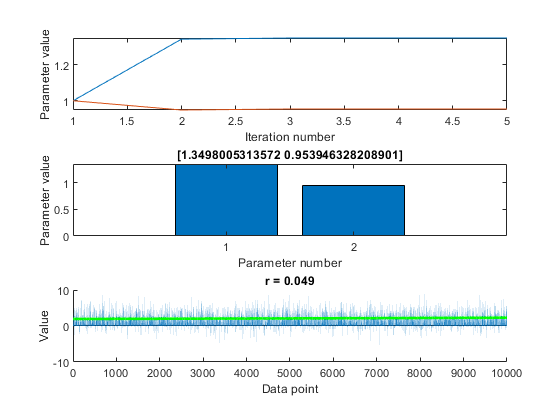


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



a = 1.3; b = 1;
x = linspace(0, 1, 10000);
%noised sample
y = a.^x + b + randn(1, 10000)*2;
options = optimset('Display','iter',...
    'OutputFcn', @(a,b,c) outputfcnplot(a,b,c,1,y));
%initial parameters a and b
params0 = [1 1];
%our model function
modelfun = @(params, x) params(1).^x + params(2);
res = lsqcurvefit(modelfun, params0, x, y, [], [], options);

disp(res);

    1.3498    0.9539



**Exercise 5. **Implement one-dimensional nearest-neighbor regression. To do this, first write a function that conforms to the declaration given below. Then, generate and visualize some data (*x-* and *y*-values). Finally, calculate the prediction of the nearest-neighbor regression model for the range of *x*-values shown in the plot and visualize the results.

nnregress.m

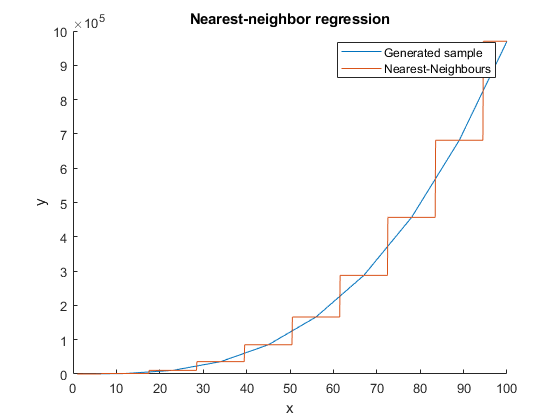

N = 10;
x =  linspace(1, 100, N);
y =  x.^3 - 3*x.^2 + 2*x + 10 + 10*rand(1, N);
xx = linspace(1, 100, 1000);
%calculate neares neighbours
yy = nnregress(xx,x,y);
figure;
hold on;
d = plot(x, y);
nn = plot(xx, yy);
title('Nearest-neighbor regression');
xlabel('x');
ylabel('y');
legend('Generated sample', 'Nearest-Neighbours');